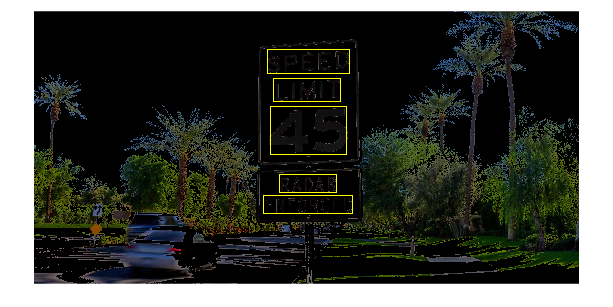


%IMAGE LOADING
filename = "speed.jpg";

img = imread(filename);
y = img;

%IMAGE TO GRAY + BINARIZATION
gray_img = im2gray(img);
th = graythresh(gray_img);
binimg = imbinarize(gray_img, th);

%MULTIPLYING TO SUPERIMPOSE
img(repmat(binimg,[1 1 3])) = 0;

%TEXT DETECTION USING PRE-TRAINED CRAFT ALGORITHM
bboxes = detectTextCRAFT(img);
Iwb = insertShape(img,"rectangle",bboxes,LineWidth=3);
figure
imshow(Iwb)

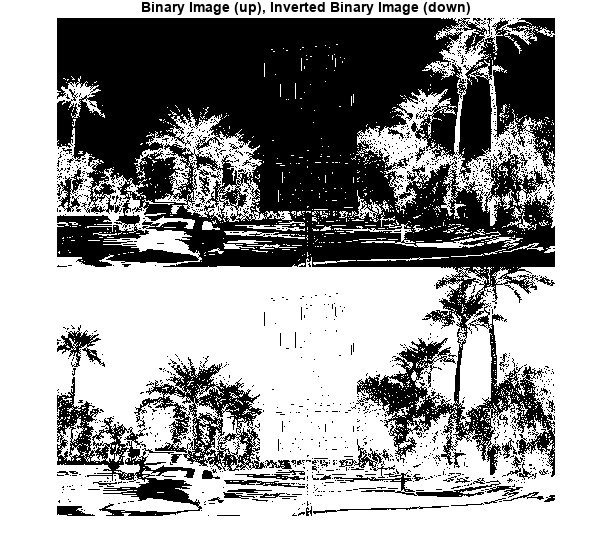


%NEW IMAGE TO GRAY AND BINARIZATION
Igray = im2gray(img);
Ibinary = imbinarize(Igray);
Icomplement = imcomplement(Ibinary);

%MONTAGE OF BOTH IMAGES
figure;
montage({Ibinary;Icomplement});
title("Binary Image (up), Inverted Binary Image (down)")

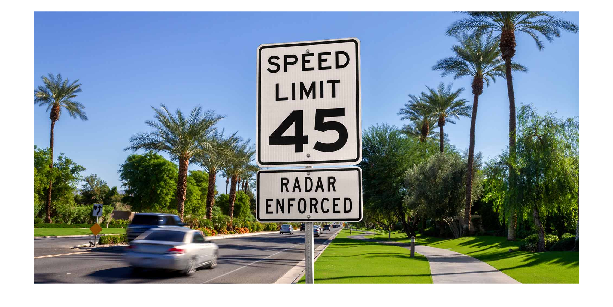


%ORDERING OF DETECTED TEXT
[~,ord] = sort(bboxes(:,2));
bbsort = bboxes(ord,:);
bbsort = sortrows(bbsort,2);

%DETERMINE IF OCR WILL USE BINARY, INVERTED BINARY, OR ORIGINAL IMAGE
%This is a user input.
type = Icomplement;


%USING OCR TO READ AND RECOGNIZE TEXT
output = ocr(type,bbsort);
recognizedWords = cat(1,output(:).Words);

%DISPLAY IMAGE WITH DETECTED TEXT
imshow(y);

showShape("rectangle",bbsort,Label=recognizedWords,Color="yellow");

Error using showShape>iValidateNumValuesEqualsNumShapes
The number of Label values must match the number of shapes.

Error in showShape>iValidateAndManageLabels (line 407)
iValidateNumValuesEqualsNumShapes(numel(labels),numShapes,'Label');

Error in showShape (line 282)
params.Label          = iValidateAndManageLabels(


%DICTATE DETECTED TEXT
sz = length(output);
L = 1;
while(L < (sz+1))

    %n = (sz+1) - L
    n = L;
    n1 = abs(n);
    rtx = output(n1).Text;
    caUserInput = rtx; % Convert from cell to string.
    NET.addAssembly('System.Speech');
    obj = System.Speech.Synthesis.SpeechSynthesizer;
    obj.Volume = 100;
    Speak(obj, caUserInput);

    L = L+1;
end


Ignore this

% I = imread("time.png");
% ig = im2gray(I);
% ie = edge(ig,"sobel",0.1);
% imwrite(ie,"ylwgray.png")
% 
% 
% % Read the image
% grayImage = imread("ylwgray.png");
% % Display the image.
% imshow(grayImage);
% S = regionprops(grayImage,'BoundingBox','Area');
% [MaxArea,MaxIndex] = max(vertcat(S.Area));
% imshow(grayImage,'InitialMagnification',20)
% %// Highlight the required object
% hold on
% rectangle('Position',S(MaxIndex).BoundingBox,'LineWidth',2,'EdgeColor','y')
% Length = S(MaxIndex).BoundingBox(3);
% Height = S(MaxIndex).BoundingBox(4);
% % Cropping the image
% % Get all rows and columns where the image is nonzero
% [nonZeroRows,nonZeroColumns] = find(grayImage);
% % Get the cropping parameters
% topRow = min(nonZeroRows(:));
% bottomRow = max(nonZeroRows(:));
% leftColumn = min(nonZeroColumns(:));
% rightColumn = max(nonZeroColumns(:));
% % Extract a cropped image from the original.
% croppedImage = grayImage(topRow:bottomRow, leftColumn:rightColumn);
% % Display the original gray scale image.
% figure
% imshow(croppedImage, []);
% 
% itx = ~(imclearborder(croppedImage));
% filledim = imfill(itx,"holes");
% imshow(itx);
% 
% rtx = ocr(itx);
% recognizedtxt = rtx.Text;
% figure;
% imshow(itx);
% text(10,10,recognizedtxt);
% % Program to do text to speech.
% % Get user's sentence
% userPrompt = 'What do you want the computer to say?';
% titleBar = 'Text to Speech';
% caUserInput = recognizedtxt; % Convert from cell to string.
% NET.addAssembly('System.Speech');
% obj = System.Speech.Synthesis.SpeechSynthesizer;
% obj.Volume = 100;
% Speak(obj, caUserInput);

